## Testing ArmPos class

### Testing ArmPos.draw

plotting random positions for each point

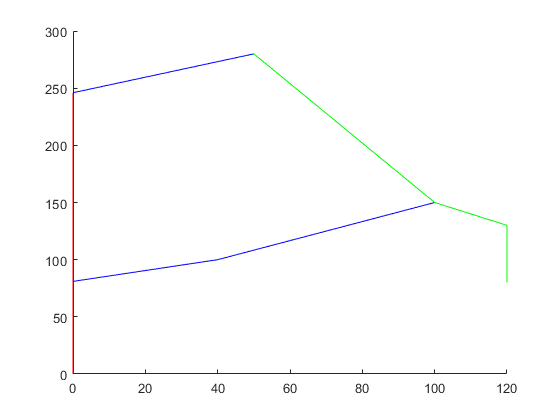

pos = ArmPos();%initiate armposition object
pos.A = [50,280]; %setting position of the arm with random numbers
pos.B = [100,150];
pos.C = [120,130];
pos = pos.setD; %also testing setD
pos.E = [40,100];
pos.draw(); %drawing the a current configuration of the arm

### Testing ACtoB

what should be seen is that the arm from A to C is now straight

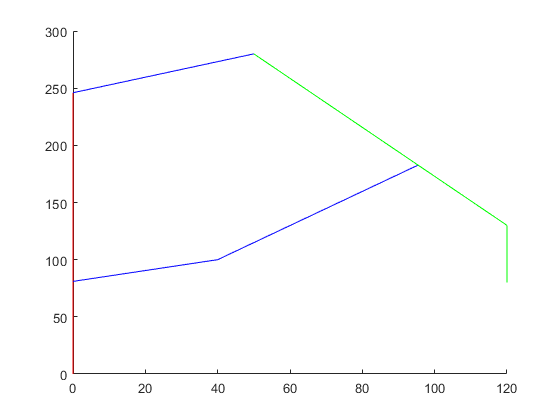

pos = pos.ACtoB();
pos.draw();

## Testing getAngle

pos.getAngle([0,0],[1,1]); % 45 degrees
pos.getAngle([0,0],[1,-1]); %-45 degrees
pos.getAngle([0,0],[-1,-1]); %-135 degrees
pos.getAngle([0,0],[-1,1]); %135 degrees

phi = 200;
phi_rad = 2*pi*phi/360

phi_rad = 3.4907

x = cos(phi_rad);
y = sin(phi_rad);
pos.getAngle([0,0],[x,y])

ans = -2.7925

pos.getAngle(pos.Z,pos.A) 

ans = 0.5972

pos = pos.getAngles

pos =   ArmPos with properties:

      L6: 120
      L7: 65
      L8: 50
       X: [0 81]
       Z: [0 246]
       A: [50 280]
       B: [95.4054 182.7027]
       C: [120 130]
       D: [120 80]
       E: [40 100]
    phiX: 0.4434
    phiZ: 0.5972
    phi1: -0.5371


## Testing validation

pos.validate()

|EX| != L3
|BE| != L4
|AZ| != L5
|AB| != L6
|BC| != L7


ans = logical
   0


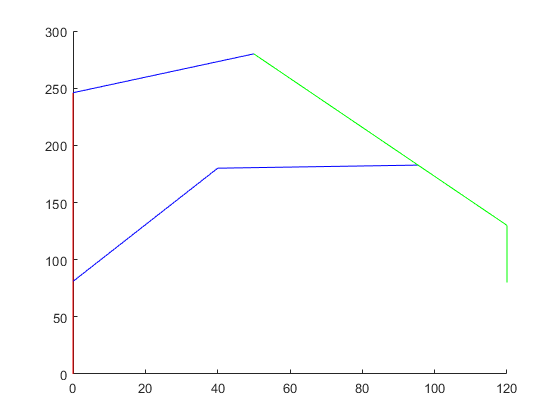

ans =   ArmPos with properties:

         L1: 81
         L2: 165
         L3: 80
         L4: 130
         L5: 130
         L6: 120
         L7: 65
         L8: 50
          X: [0 81]
          Z: [0 246]
    phiXmin: -10
    phiXmax: 140
    phiZmin: -45
    phiZmax: 80
          A: [50 280]
          B: [95.4054 182.7027]
          C: [120 130]
          D: [120 80]
          E: [40 180]
       phiX: 0
       phiZ: 0
       phi1: 0


pos.draw()

pos.E - pos.B

ans =   -55.4054   -2.7027
